# Live script of triple pendulum

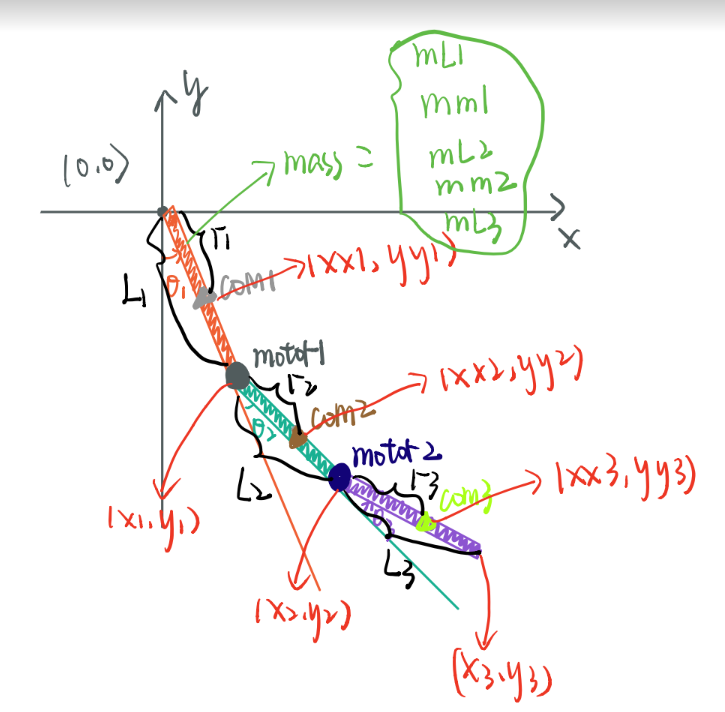    

clear;
close all;
clc;

fprintf('Deriving triple pendulum equations\n');

fprintf('\tInitializing generalized coordinates, velocities, accelerations, and forces...\n');
% Generalized coordinates:
% theta_1: angle of top link, ccw+ wrt x-axis
% theta_2: angle of mid link, ccw+ wrt x-axis
% theta_3: angle of bot link, ccw+ wrt x-axis
syms theta_1 theta_2 theta_3 real
q = [theta_1; theta_2; theta_3]

% Generalized velocities:
% dtheta_1: first derivative of top link angle wrt time
% dtheta_2: first derivative of mid link angle wrt time
% dtheta_3: first derivative of bot link angle wrt time
syms dtheta_1 dtheta_2 dtheta_3 real
dq = [dtheta_1; dtheta_2; dtheta_3];

% Generalized accelerations:
% ddtheta_1: second derivative of the top link angle wrt time
% ddtheta_2: second derivative of the mid link angle wrt time
% ddtheta_3: second derivative of the bot link angle wrt time
syms ddtheta_1 ddtheta_2 ddtheta_3 real
ddq = [ddtheta_1; ddtheta_2; ddtheta_3];

% Generalized forces:
syms u real % force on the cart, in the x-direction

fprintf('\t...done.\n');

%% Define kinematics variables
fprintf('\tInitializing kinematics variables...\n');

% x-coordinates of the top, mid, bot links CoM:
syms x_com_top x_com_mid x_com_bot real

% y-coordinates of the top, mid, bot links CoM:
syms y_com_top y_com_mid y_com_bot real

% Dimensions: distance joint to top, mid, bot link CoM:
syms r_com_top r_com_mid r_com_bot real

% Dimensions: length of the top, mid, bot link
syms l_top l_mid l_bot real

% x-coordinates of top, mid, bot tip:
syms x_tip_top x_tip_mid x_tip_bot real

% y-coordinates of top, mid, bot tip:
syms y_tip_top y_tip_mid y_tip_bot real
% Note: the dynamics don't care where the pendulum tip is (only the 
% pendulum CoM), but keeping track of the tip will be helpful for 
% visualizing the robot (could also be helpful for some control tasks).
fprintf('\t...done.\n');

%% Define inertial (and other) parameters
fprintf('\tInitializing inertial (and other) parameters...\n');

% Mass of top, mid, bot link:
syms m_top m_mid m_bot real

% Rotational inertia of top, mid, bot link:
syms I_top I_mid I_bot real

% Viscous damping at each joint:
b = sym('b',[numel(q),1],'real');
% Note: we'll account for damping at each joint (ground-cart and 
% cart-pendulum) but we can set each damping constant to 0 later if we
% want.

% Other variables
g = sym('g','real'); % gravity
t = sym('t','real'); % time

fprintf('\t...done.\n');

%% Forward kinematics
fprintf('\tGenerating forward kinematics equations...\n');

% compute the (x,y) location of the top link's CoM:
x_com_top = r_com_top*cos(theta_1);
y_com_top = r_com_top*sin(theta_1);

fprintf('\tThe (x,y) location of the top link CoM is\n')
display(x_com_top)
display(y_com_top)

% compute the (x,y) location of the top link's tip:
x_tip_top = l_top*cos(theta_1);
y_tip_top = l_top*sin(theta_1);

%compute the (x,y) location of the mid link's CoM:
x_com_mid = x_tip_top + r_com_mid*cos(theta_1+theta_2);
y_com_mid = y_tip_top + r_com_mid*sin(theta_1+theta_2);

fprintf('\tThe (x,y) location of the middle link CoM is\n')
display(x_com_mid)
display(y_com_mid)

%compute the (x,y) location of the mid link's tip:
x_tip_mid = x_tip_top + l_mid*cos(theta_1+theta_2);
y_tip_mid = y_tip_top + l_mid*sin(theta_1+theta_2);

%compute the (x,y) location of the bot link's CoM:
x_com_bot = x_tip_mid + r_com_bot*cos(theta_1+theta_2+theta_3);
y_com_bot = y_tip_mid + r_com_bot*sin(theta_1+theta_2+theta_3);

fprintf('\tThe (x,y) location of the bottom link CoM is\n')
display(x_com_bot)
display(y_com_bot)

%compute the (x,y) location of the bot link's tip:
x_tip_bot = x_tip_mid + l_bot*cos(theta_1+theta_2+theta_3);
y_tip_bot = y_tip_mid + l_bot*sin(theta_1+theta_2+theta_3);

% create a 2x6 array to hold all forward kinematics (FK) outputs:
FK = [x_com_top, x_tip_top, x_com_mid, x_tip_mid, x_com_bot, x_tip_bot;
      y_com_top, y_tip_top, y_com_mid, y_tip_mid, y_com_bot, y_tip_bot];
display(FK)

% generate a MATLAB function to compute all the FK outputs:
matlabFunction(FK,'File','autogen_fwd_kin');
% Note: this autogenerated function will make plotting/animation easier
% later. Could also help with some control tasks.
fprintf('\t...done.\n');

%% Derivatives
fprintf('\tGenerating time derivatives of the kinematics equations...\n');
% Neat trick to compute derivatives using the chain rule
% from https://github.com/MatthewPeterKelly/OptimTraj/blob/master/demo/fiveLinkBiped/Derive_Equations.m
derivative = @(in)( jacobian(in,[q;dq])*[dq;ddq] );

% CoM x-velocities:
syms dx_com_top dx_com_mid dx_com_bot real
% CoM y-velocities:
syms dy_com_top dy_com_mid dy_com_bot real

dx_com_top = derivative(x_com_top);
dy_com_top = derivative(y_com_top);
dx_com_mid = derivative(x_com_mid);
dy_com_mid = derivative(y_com_mid);
dx_com_bot = derivative(x_com_bot);
dy_com_bot = derivative(y_com_bot);

fprintf('\t...done.\n');

%% Kinetic energy
fprintf('\tGenerating kinetic energy equation...\n');

syms ke_top ke_mid ke_bot KE real

% kinetic energy of each link:
ke_top = (1/2)*m_top*(dx_com_top^2 + dy_com_top^2) + (1/2)*I_top*(dtheta_1^2); 
ke_mid = (1/2)*m_mid*(dx_com_mid^2 + dy_com_mid^2) + (1/2)*I_mid*(dtheta_2^2);
ke_bot = (1/2)*m_bot*(dx_com_bot^2 + dy_com_bot^2) + (1/2)*I_bot*(dtheta_3^2);

% total kinetic energy:
KE = ke_top + ke_mid + ke_bot;

fprintf('\t...done.\n');

%% Potential energy
fprintf('\tGenerating potential energy equation...\n');

syms pe_top pe_mid pe_bot PE real

% potential energy of each link:
pe_top = m_top*g*y_com_top;
pe_mid = m_mid*g*y_com_mid;
pe_bot = m_bot*g*y_com_bot;

%total potential energy:
PE = pe_top + pe_mid + pe_bot;

fprintf('\t...done.\n');

%% Lagrangian
fprintf('\tGenerating Lagrangian...\n');

syms L real
L = KE - PE;
L = simplify(L);

fprintf('\tThe Lagrangian is\n')
display(L)

fprintf('\t...done.\n');

%% Euler-Lagrange equations
fprintf('\tGenerating Euler-Lagrange equations of motion...\n')

% Note: the Euler-Lagrange equations of motion are
%   d(del L/del dq)/dt - (del L/del qa) = generalized forces;
% I did not include damping in my Lagrangian (although it can be done, at
% least for viscous damping) so I have to lump it in with the other
% generalized forces (in this case, the only other generalized force is the
% control input u, i.e. the force applied horizontally to the cart).

% Variable initializations:
ELeq_term1  = sym('ELeq_term1',[numel(q),1],'real'); % d(del L/del dq)/dt
ELeq_term2  = sym('ELeq_term2',[numel(q),1],'real'); % del L/del qa
ELeq_damping= sym('ELeq_damping',[numel(q),1],'real'); % joint damping
ELeq_LHS    = sym('ELeq_LHS',[numel(q),1],'real');

for i = 1:numel(q)
    ELeq_term1(i) = simplify(derivative(diff(L,dq(i))));
    ELeq_term2(i) = simplify(diff(L,q(i)));
    ELeq_damping(i) = -b(i)*dq(i);
    ELeq_LHS(i) = ELeq_term1(i) - ELeq_term2(i) - ELeq_damping(i);
    ELeq_LHS(i) = simplify(ELeq_LHS(i));
end

fprintf('\t...done.\n')

%% Put E-L eq in manipulator form
fprintf('\tPutting Euler-Lagrange equations into manipulator form...\n');
fprintf('\t\tBuilding M, C, and G...\n');

% Note: the manipulator equation
%       M*ddq + C*dq + G = U

% The mass matrix M is a matrix of partial derivatives of ELeq_LHS with
% respect to ddq.

% The gravity vector G is a column vector of the generalized forces due to
% gravity. Consequently, G is linear in "g" (the scalar acceleration due to
% gravity).

% The coriolis term C*dq is everything else in ELeq_LHS that is not already
% included in M or G.

M = sym('M',[numel(q),numel(q)],'real');
C = sym('C',[numel(q),numel(q)],'real');
G = sym('G',[numel(q),1],'real');

for i = 1:numel(q)
    fprintf('\t\ti = %d\n',i);
    fprintf('\t\t\tM(%d,:)...\n',i)
    for j = 1:numel(q)
        fprintf('\t\t\t\tj = %d\n',j);
        M(i,j) = diff(ELeq_LHS(i),ddq(j)); %TODO
        M(i,j) = simplify(M(i,j));
    end
    
    fprintf('\t\t\tG(%d)...\n',i)
    G(i) = diff(ELeq_LHS(i),g)*g; % G is linear in g
    
    fprintf('\t\t\tC(%d)...\n',i);
    % C*dq is everything else:
    for j = 1:numel(q)
        fprintf('\t\t\t\tj = %d\n',j);
        C(i,j) = diff((ELeq_LHS(i) - (M(i,:)*ddq + G(i))),dq(j));
    end
    C(i) = simplify(C(i)); % takes some time to execute
end

fprintf('\t\t...done building M, C, and G.\n');

% compute and store inv(M):
fprintf('\t\tComputing inv(M)...\n')
Minv = sym('Minv',[numel(q),numel(q)],'real');
Minv = simplify(inv(M));
fprintf('\t\t...done.\n')

fprintf('\t\tGenerating MATLAB functions...\n');
matlabFunction(M,'File','autogen_mass_matrix');
matlabFunction(C,'File','autogen_coriolis_matrix');
matlabFunction(G,'File','autogen_grav_vector');
fprintf('\t\t...done.\n');

fprintf('\t...done putting Euler-Lagrange equations into manipulator form.\n');

%% Generate (nonlinear) state-space model from manipulator equation
fprintf('\tConverting manipulator equation to state-space form...\n');

f_ss = sym('f_ss',[2*numel(q),1],'real'); % drift vector field
g_ss = sym('g_ss',[2*numel(q),1],'real'); % control vector field


temp_drift = simplify(-Minv*(C*dq + G)); % TODO, also use simplify(...)
temp_ctrl = simplify(Minv*[0,0; 1,0; 0,1]); % actuators at shoulders and hips

% Build state-space representation:
for i = 1:numel(q)
    f_ss(i)   = dq(i);
    g_ss(i,:)   = [0,0];
    f_ss(i + numel(q)) = temp_drift(i);
    g_ss(i + numel(q),:) = temp_ctrl(i,:);
end